2. (Take-home 2) You're going to estimate the integral


$$
I = \int_{-\infty}^{\infty} \frac{1}{1 + x^2}\cos(30(x - 1)^2)\mathrm{d}x $$


numerically to high accuracy. **Read the question entirely before starting, and note the hints.**

a) As a warm-up exercise, write code to evaluate the integral $$\int_{-\infty}^{\infty} e^{-cx^2}$
$ numerically, where $$c \in \mathbb{R}$$ is a constant. By checking against the analytic answer, perform a convergence test. Aim to get an answer accurate to 13-14 digits.

*Hint: *You will find that there are multiple parameters in your numerical quadrature routine. Check convergence against all of these, either in the form of heat map(s), or by converging in one parameter first, then converging in the second parameter, etc. You can pick any quadrature method you like, bonus points if it's really efficient (needs few function evaluations)! Convergence testing means that you vary a parameter (usually something like increase the number of quadrature nodes) until the answer settles.

b) Write the integrand of $$I$$ as the real part of some other function $$g(z)$$. At what point is the **phase** of the function $$g(z)$$ stationary? (I.e. when is its derivative zero?)

c) Use the code snippet below to plot $$\text{Re}( g(z))$$ in the complex plane. By looking at the plot, find a path that goes through the stationary point along which $$\text{Re}(g(z))$$ is smooth (does not oscillate), and plot it over the existing figure.

d) What function $ $h(x)$ $does $$g(z)$ $behave as along the path you've chosen? 

*Hint:* Plotting it might help, and it should look familiar from the earlier parts of this question. 

e) Parameterize the path from c) in the form $$z = f(s)$$, where $$s$$ is a real parameter, and rewrite your integral of $$g(z)$$ in terms of $$s$$ along this path. 

*Hint*: Don't forget to scale your integration variable, transform the integration limits, and rewrite the integrand in this new variable. 

f) Write code that evaluates the contour integral from e). Use your answer from a) to get values for the parameters you need for the numerical integral. Then take the real part, and that's your approximation to $$I$$!

What you did here was you interpreted the integral $$I$$ as that of an analytic function on the real axis. Since the function $$g(z)$ $is analytic everywhere, this integration contour may be deformed without changing the value of the integral! So you identified and picked a contour along which $$g(z)$ $is smooth, and so is easier to integrate. It's a beautiful trick.

g) Estimate theoretically or find experimentally how much more computational work (I'm looking for a multiplicative factor here, e.g. "ten times") you'd need if you were to evaluate the integral $ $I$ $on the real axis. 

*Hints*:

- For the theoretical estimate:

  - If a function has $$n$$ roots, what's the minimum degree interpolating polynomial you expect to give a "not garbage" approximation to it?

  - What does that say about how the number of quadrature nodes you would need to integrate it?

  - So if an oscillatory function goes through zero $$n$$ times, how does the number of quadrature nodes you'll need to integrate it scale with $$n$$? (An $$\mathcal{O}(f(n))$$ answer is enough.)

  - Finally, what does this mean for the scaling of $$n$$, the number of quadrature nodes required, with $$\omega$$, the frequency of the oscillatory function (if the integration interval is fixed)?

- For the experimental estimate:

  - You can time the execution of some bit of code using `time.time()` in Python and `tic` + `toc` in MATLAB, check the documentation for examples.

  - When timing a script, always run it many times in a `for` loop, and average over the number of loops.

  - You can also just count the quadrature nodes!

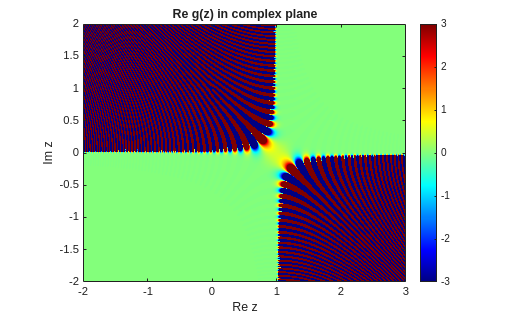

g = @(z) ; % Your function here
gx = -2:1e-3:3;
gy = -2:1e-3:2;
[xx, yy] = meshgrid(gx,gy);
zz = xx+1i*yy;
gz = g(zz);
figure;
imagesc(gx,gy,real(gz));
clim(3*[-1 1]);
axis xy equal tight;
xlabel('Re z');
ylabel('Im z');
colormap('jet'); % If you're colorblind, comment out this line
colorbar;
title('Re g(z) in complex plane')